## Circuit Creation

ck = circuit();

R = 50;
C = 1e-9;
L = 1e-5;

add(ck, [1 2], resistor(1e3));
add(ck, [1 2], capacitor(C));

setports(ck, [1 2], [1 2]);

## S-Parameters and Rational Fit

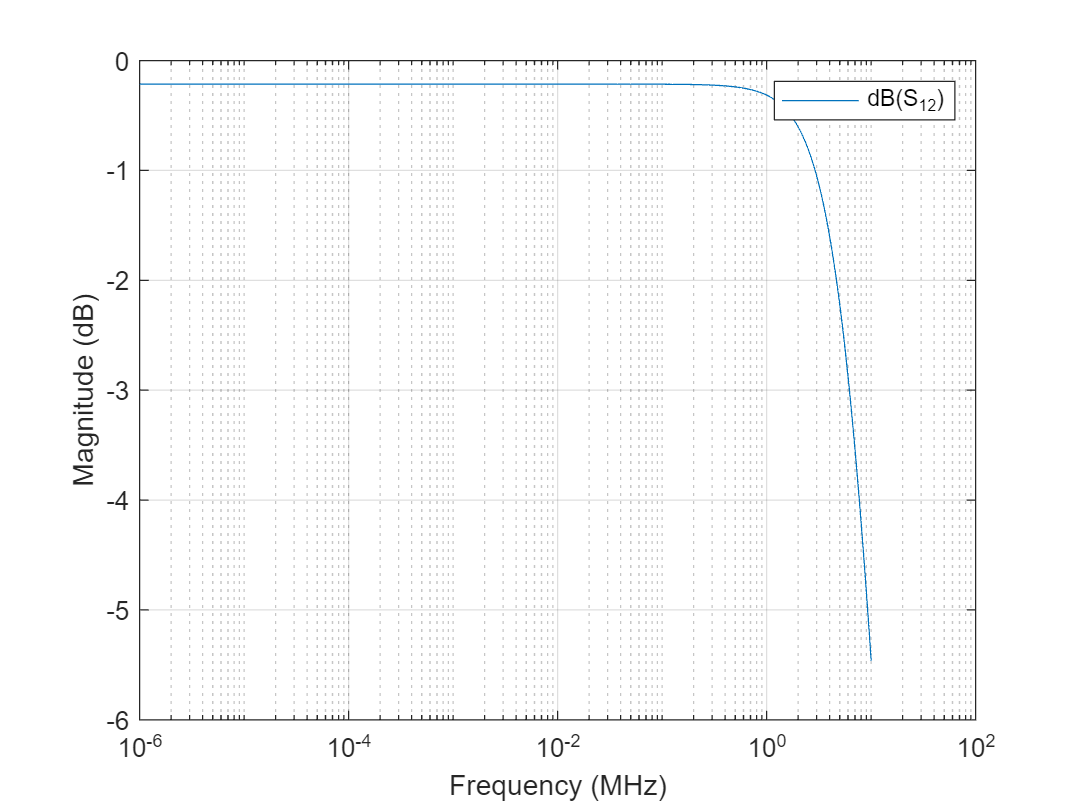

freqs = linspace(1e0, 1e7, 800);
s = sparameters(ck, freqs);
rfplot(s, 1, 2);
xscale('log');

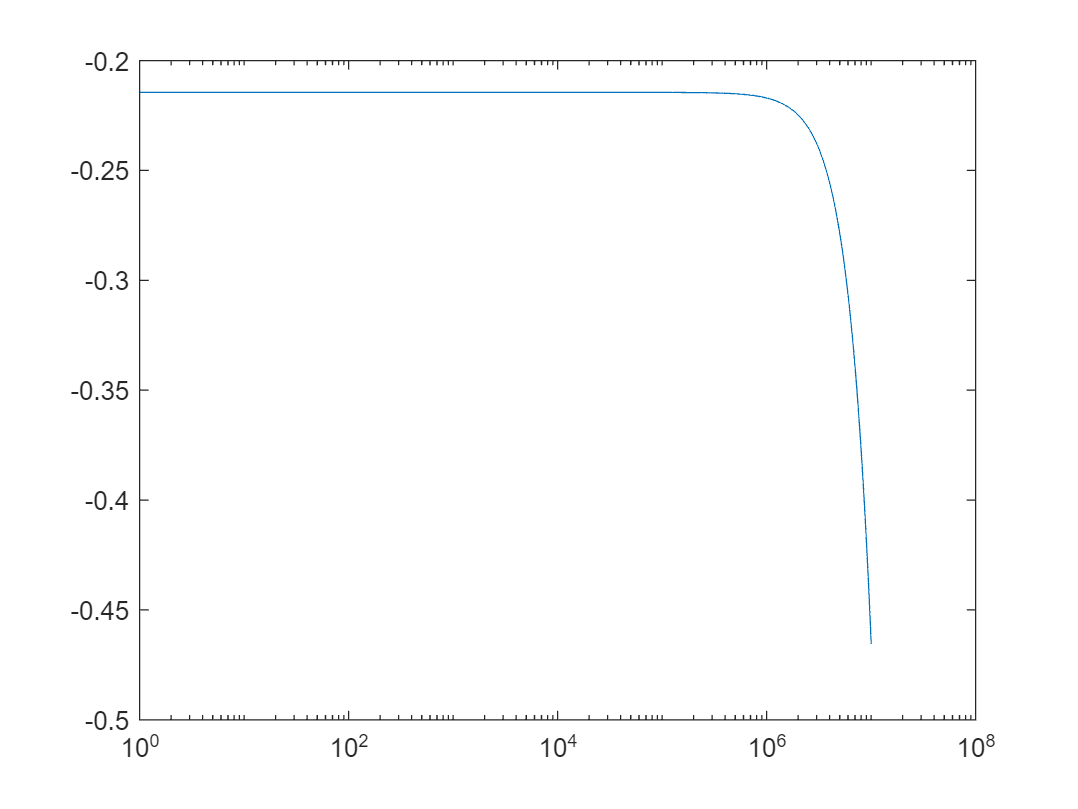

S = rational(s, 'TendsToZero', false);
[z, p, k] = zpk(S);
fit = zpk(z, p, k);
F = freqresp(fit, freqs);
plot(freqs, db(reshape(F(1, 2, :), 1, [])));
xscale("log");

% F = freqresp(S, freqs);
% plot(freqs, db(reshape(F(1,2,:), 1, [])));
% hold on;
% grid on;
% xscale('log');
% plot(freqs, db(reshape(F(1,2,:), 1, [])));
% plot(freqs, db(reshape(F(2,1,:), 1, [])));
% plot(freqs, db(reshape(F(2,2,:), 1, [])));